% Load the image
imageFile = 'C:\Users\regin\Documents\MATLAB\extracted_images\Experiment_1\left\left_image_2.jpg'; % Replace with your image file name
% Load the image
image = imread(imageFile);

% Display the image
imshow(image);
title('Select two points for length measurement');

% Get user input for the length measurement
disp('Click on the two endpoints of the reference length.');

Click on the two endpoints of the reference length.


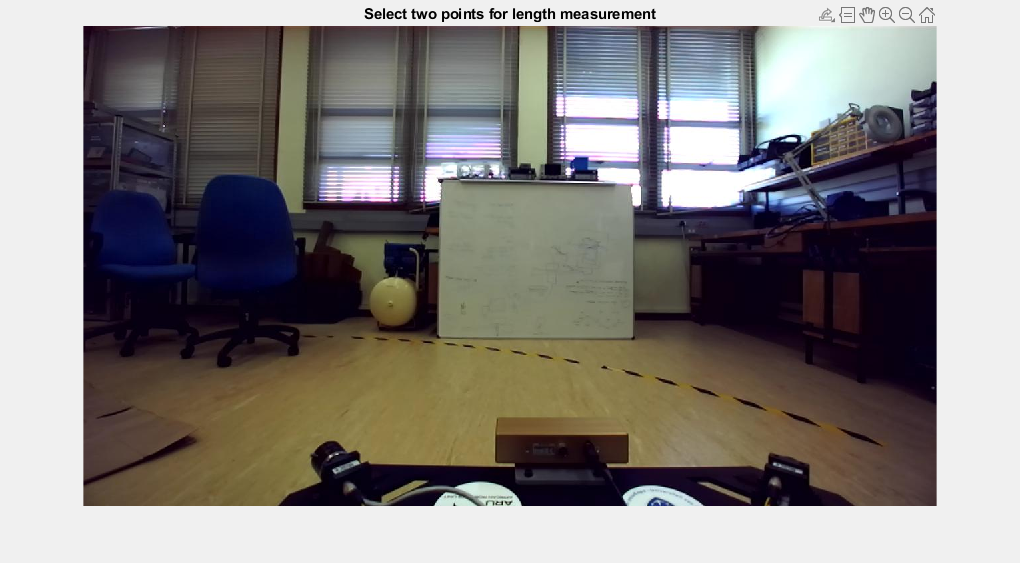

[x_length, y_length] = ginput(2);


% Display the image again for width measurement
imshow(image);
title('Select two points for width measurement');

% Get user input for the width measurement
disp('Click on the two endpoints of the reference width.');

Click on the two endpoints of the reference width.


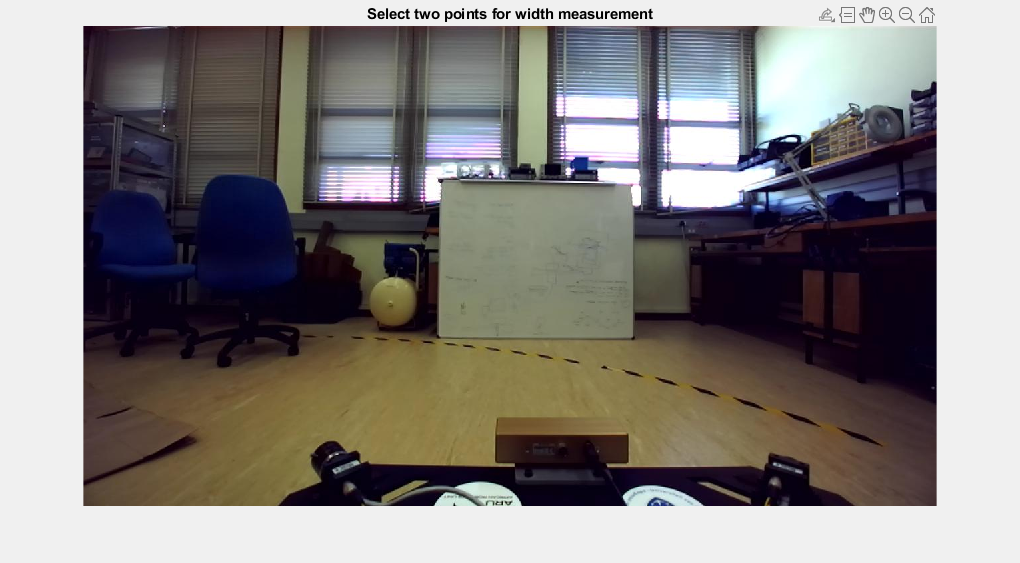

[x_width, y_width] = ginput(2);


% Calculate the pixel distances
pixel_length = sqrt((x_length(2) - x_length(1))^2 + (y_length(2) - y_length(1))^2);
pixel_width = sqrt((x_width(2) - x_width(1))^2 + (y_width(2) - y_width(1))^2);

% Define the physical length and width of the reference object in meters
ref_length_m = 1.52; % for example, 1 meter
ref_width_m = 1.22;  % for example, 0.5 meters

% Calculate the length and width per pixel
length_per_pixel = ref_length_m / pixel_length;
width_per_pixel = ref_width_m / pixel_width;

% Display the results
fprintf('Length per pixel: %f meters/pixel\n', length_per_pixel);

Length per pixel: 0.006333 meters/pixel


fprintf('Width per pixel: %f meters/pixel\n', width_per_pixel);

Width per pixel: 0.004349 meters/pixel
